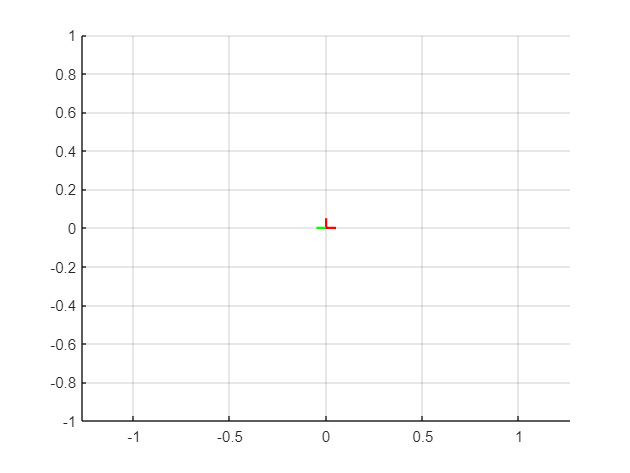

%Reprezentare configuratie(Desen)
%intrare: Variabile din cuple
 q1=0; %rotatie 
 q2=0; %rotatie 
 q3=0; %rotatie
 q4=0; %rotatie
 q5=pi/2; %rotatie
 %iesire:vectorul de pozitie al efectorului
 desenMGDlicenta(q1,q2,q3,q4,q5)

function desenMGDlicenta(q1,q2,q3,q4,q5)
    figure
    l1 = 0.5;
    l2 = 0.5;
    l3 = 0.5;
    l4 = 0.5;
    l5 = 0.5;
    P0 = [0; 0; 0; 1];

    % Transformarea T10
    T10 = [cos(q1), -sin(q1), 0, 0; ...
           sin(q1),  cos(q1), 0, 0; ...
               0,        0,   1, 0; ...
               0,        0,   0, 1];

    % Transformarea T21
    T21 = [1, 0, 0, 0; ...
           0, cos(q2), -sin(q2), 0; ...
           0, sin(q2),  cos(q2), l1; ...
           0, 0, 0, 1];

     % Transformarea T32
   T32 = [1, 0, 0, 0; ...
           0,        cos(q3),     -sin(q3),   0; ...
           0, sin(q3),  cos(q3),l2; ...
           0, 0, 0, 1];


     T43 = [1, 0, 0, 0; ...
           0,        cos(q4),     -sin(q4),   0; ...
           0, sin(q4),  cos(q4),l3; ...
           0, 0, 0, 1];

     T54 = [cos(q5), -sin(q5), 0, 0; ...
           sin(q5),  cos(q5), 0, 0; ...
               0,        0,   1, l4; ...
               0,        0,   0, 1];

   Te5 = [ 1, 0, 0, 0;...
           0, 1, 0, 0;...
           0, 0, 1, l5;...
           0, 0, 0, 1;];

    % Transformare totală până la a doua cuplă
    T20 = T10 * T21;
    T30 = T10 *T21*T32;
    T40 = T10 *T21*T32*T43;
    T50 = T10 *T21*T32*T43*T54;
    Te5 = T10 * T21 * T32 * T43 * T54 * Te5;

    % Puncte de poziție
    p0 = T10 * P0;       % poziția primei articulații
    p1 = T20 * P0;
    p2 = T30 * P0;
    p3 = T40 * P0;
    p4 = T50 * P0;
    p5 = Te5 * P0;
    % poziția celei de-a doua articulații

    hold on
    % Axele primei articulații
    quiver3(p0(1), p0(2), p0(3), T10(1,1), T10(2,1), T10(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
    quiver3(p0(1), p0(2), p0(3), T10(1,2), T10(2,2), T10(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
    quiver3(p0(1), p0(2), p0(3), T10(1,3), T10(2,3), T10(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

    % Axele celei de-a doua articulații (în sistem global)
    quiver3(p1(1), p1(2), p1(3), T20(1,1), T20(2,1), T20(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
    quiver3(p1(1), p1(2), p1(3), T20(1,2), T20(2,2), T20(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
    quiver3(p1(1), p1(2), p1(3), T20(1,3), T20(2,3), T20(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

    quiver3(p2(1), p2(2), p2(3), T30(1,1), T30(2,1), T30(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
    quiver3(p2(1), p2(2), p2(3), T30(1,2), T30(2,2), T30(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
    quiver3(p2(1), p2(2), p2(3), T30(1,3), T30(2,3), T30(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

    quiver3(p3(1), p3(2), p3(3), T40(1,1), T40(2,1), T40(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
    quiver3(p3(1), p3(2), p3(3), T40(1,2), T40(2,2), T40(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
    quiver3(p3(1), p3(2), p3(3), T40(1,3), T40(2,3), T40(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

    quiver3(p4(1), p4(2), p4(3), T50(1,1), T50(2,1), T50(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
    quiver3(p4(1), p4(2), p4(3), T50(1,2), T50(2,2), T50(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
    quiver3(p4(1), p4(2), p4(3), T50(1,3), T50(2,3), T50(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

   quiver3(p5(1), p5(2), p5(3), Te5(1,1), Te5(2,1), Te5(3,1), 0.05, 'r', 'LineWidth', 1.5); % X
   quiver3(p5(1), p5(2), p5(3), Te5(1,2), Te5(2,2), Te5(3,2), 0.05, 'g', 'LineWidth', 1.5); % Y
   quiver3(p5(1), p5(2), p5(3), Te5(1,3), Te5(2,3), Te5(3,3), 0.05, 'b', 'LineWidth', 1.5); % Z

    % Linia între articulații
    line([p0(1), p1(1)], [p0(2), p1(2)], [p0(3), p1(3)], 'Color', 'b', 'LineWidth', 3);
    line([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'Color', 'b', 'LineWidth', 3);
    line([p2(1), p3(1)], [p2(2), p3(2)], [p2(3), p3(3)], 'Color', 'b', 'LineWidth', 3);
    line([p3(1), p4(1)], [p3(2), p4(2)], [p3(3), p4(3)], 'Color', 'r', 'LineWidth', 3);
    line([p4(1), p5(1)], [p4(2), p5(2)], [p4(3), p5(3)], 'Color', 'g', 'LineWidth', 3);

    grid on;
    xlim([-1, 1]);
    ylim([-1, 1]);
    axis equal;
    disp('T10 ='); disp(T10);
    disp('T21 ='); disp(T21);
    disp('T32 ='); disp(T32);
    disp('T43 ='); disp(T43);
    disp('T54 ='); disp(T54);
    disp('Te5 ='); disp(Te5);

end